CASE = 1 % 0 is Step Reference Aggregated Power, 1 is Fluctuating Reference Aggregated Power

CASE = 1

MODE = 0 % 0 is using randomly generated topology and parameters, 1 is using history communication topology and IACs parameters

MODE = 0

% Generating topology
% different topology will result in different control effect
if(MODE==0)
    N=500; % the number of IACs
    L=zeros(N,N);
    eig2=0;
    while(eig2<0.001)
    L=zeros(N,N);    
    for i=1:N
        p=0;
        while(p<0.6)
            p=rand;
        end
        for j=i+1:N
            if(rand>p)
                L(i,j)=-1;
                L(j,i)=-1;
            end
        end
        L(i,i)=-sum(L(i,1:N));
    end
    eigen=eig(L);
    eig2=eigen(2);
    end
    L;
    eig(L);
    D=zeros(N,N);
    while(D==zeros(N,N))
    for i=1:N
        if(rand>0.85)
            D(i,i)=1;
        end
    end
    end
    sum(D,2);
end

% Setting the parameters of the IACs
% different parameters will result in different control effect
if(MODE==0)
    CT=1.9+0.2*rand(N,1); 
    RT=(1.9+0.2*rand(N,1))*10; 
    theta=(2.3+0.4*rand(N,1))/10;
    Tref=22+2*rand(N,1);
    dT=1.8+0.4*rand(N,1);
end
Ta=32;
A=diag(-1./(CT.*RT));
B=diag(-theta./(2*dT.*CT));
C=diag((Ta-Tref+dT)./(2*dT.*CT.*RT));


beta=0.25;
% kai=0.025;
% P_obj=2*N;
% rho0=0.72;
P0=5.6;

% Setting the parameters of the power system
df_t=zeros(1,2000001);
df_t_delay=zeros(1,2000001);
dPti_t=zeros(1,2000001);
u_P=0;
KP=-0.005;
KI=-0.01;
c_P=0;
c_I=0;
XP=zeros(4,1);   %df dPti dXgi dPgi 
TH=0.1;
TD=0.002;
TCA=4;
TCB=30;
TT=0.2;
TG=0.3;
RG=3.6;
AT=[-TD/2/TH,1/2/TH,0,0;
    0,-1/TT,1/TT,0;
    -TCA/TCB/TG/RG,0,-1/TCB,(TG-TCA)/TCB/TG;
    -1/RG/TG,0,0,-1/TG];
BT=[0;0;TCA/TCB/TG;1/TG];
H=[-1/2/TH;0;0;0];

CommDelayII=0.1;
CommDelayAI=0.1;
CommPeriodAI=0.2;
CommPeriodII=0.1;
fSample=0.2;
CtrlPeriod=0.05;
ResponseTime=0.05;

% Initializing the state of IACs
x=0.3+0.5*rand(N,1);
v=zeros(N,1);
P_init=zeros(N,1);
u=zeros(N,1);
for i=1:N
    P_init(i)=0.25*P0+0.1*P0*rand;
end
P=P_init;
for i=1:N
    v(i)=A(i,i)*x(i)+B(i,i)*P(i)+C(i,i);
end

if(MODE==0&&CASE==1)
    dPL=0.05*randn(1,200001);
    dPL(1:round(220/0.01)+1)=0; %%% generate random load fluctuation every 0.01s 
    dPL1=dPL(1:end-1);
    dPL2=[dPL1;dPL1;dPL1;dPL1;dPL1;dPL1;dPL1;dPL1;dPL1;dPL1];
    dPL3=reshape(dPL2,[1,2000000]);
    dPL=[dPL3,dPL(end)];
end
P_t=zeros(1,2000001);
P_t_delay=zeros(1,2000001);
Pobj_t=zeros(1,2000001);
Pobj_t_delay=zeros(1,2000001);
u_t=zeros(N,2000001);
x_t=zeros(N,2000001);
v_t=zeros(N,2000001);
x_t_delay=zeros(N,2000001);
v_t_delay=zeros(N,2000001);
Pi_t=zeros(N,2000001);
Pi_t_delay=zeros(N,2000001);
P_sum=sum(P);
dPTCLs=0;
dPTCLs_t=zeros(1,2000001);
dP=0;
% drop=360/2;
drop=0.72*N;
xxx=zeros(N,1);
vvv=zeros(N,1);

% Frequency deviation with IACs participation 
T=500

T = 500

for t=0:0.001:T
    CommDelayIIN=fix(CommDelayII/0.001); 
    CommDelayAIN=fix(CommDelayAI/0.001); 
    CommPeriodAIN=fix(CommPeriodAI/0.001); 
    CommPeriodIIN=fix(CommPeriodII/0.001); 
    fSampleN=fix(fSample/0.001); 
    CtrlPeriodN=fix(CtrlPeriod/0.001); 
    ResponseTimeN=fix(ResponseTime/0.001); 
    n=round(t/0.001)+1;
    if(t>220&&CASE==0)
        dPL=0.03;
    elseif(CASE==0)
        dPL=0;
    end
    c_I=c_I+0.001*XP(1);
    c_P=XP(1);
    u_P=KP*c_P+KI*c_I;
    
    if(CASE==1)
        XP=XP+0.001*( AT*XP + BT*u_P + H*(0.8*dPL(n)+0.2*dPTCLs));
    elseif(CASE==0)
        XP=XP+0.001*( AT*XP + BT*u_P + H*(0.8*dPL+0.2*dPTCLs));
    end
    
    if(t<220) % Running to steady state for the ease of comparison
        kai=0.08;
        P_obj=1.8*N;
        P_nom=P_sum;
        if(CASE==0)
            dPL=0;
        end
    else 
        kai=0.25;
        
        if(mod(t,fSample)==0)
            P_obj=P_nom + drop * XP(1); % power system frequency sampling
        end
        
        dPTCLs=(P_sum-P_nom)/P_nom;
        if(CASE==0)
            dPL=0.03;  % percentage
        end
    end
    
        Pi=inv(B)*(v-A*x-C*ones(N,1));
        P_sum=P_sum + 0.001*sum(u);
        
        if(t>CommDelayAI&&mod(t,CommPeriodAI)==0) % time-delay between aggregator and IACs
            dP=Pobj_t(n-CommDelayAIN)-P_t(n-CommDelayAIN);
        end
        
        if(t>CommDelayII&&mod(t,CommPeriodII)==0) % time-delay between IACs
            xxx=x_t(1:N,n-CommDelayIIN);
            vvv=v_t(1:N,n-CommDelayIIN);
        end
        
        if(mod(t,CtrlPeriod)==0) % control peroid
            u=beta*L*xxx+beta*L*vvv+kai*D*ones(N,1)*sign(dP);
        end
        x=x+0.001*v;
        
        
        if(t>ResponseTime) % response time
            v=v+0.001*(A*v+B*u_t(1:N,n-ResponseTimeN)); 
        else
            v=v+0.001*(A*v);
        end

    dPTCLs_t(n)=dPTCLs;   
    Pi_t(1:end,n)=Pi;
    P_t(n)=P_sum;
    Pobj_t(n)=P_obj;
    x_t(1:N,n)=x;
    v_t(1:N,n)=v;
    u_t(1:N,n)=u;
    df_t(n)=XP(1);

    if(mod(n,1000)==0)
        n
    end
end 

n = 1000

n = 2000

n = 3000

n = 4000

n = 5000

n = 6000

n = 7000

n = 8000

n = 9000

n = 10000

n = 11000

n = 12000

n = 13000

n = 14000

n = 15000

n = 16000

n = 17000

n = 18000

n = 19000

n = 20000

n = 21000

n = 22000

n = 23000

n = 24000

n = 25000

n = 26000

n = 27000

n = 28000

n = 29000

n = 30000

n = 31000

n = 32000

n = 33000

n = 34000

n = 35000

n = 36000

n = 37000

n = 38000

n = 39000

n = 40000

n = 41000

n = 42000

n = 43000

n = 44000

n = 45000

n = 46000

n = 47000

n = 48000

n = 49000

n = 50000

n = 51000

n = 52000

n = 53000

n = 54000

n = 55000

n = 56000

n = 57000

n = 58000

n = 59000

n = 60000

n = 61000

n = 62000

n = 63000

n = 64000

n = 65000

n = 66000

n = 67000

n = 68000

n = 69000

n = 70000

n = 71000

n = 72000

n = 73000

n = 74000

n = 75000

n = 76000

n = 77000

n = 78000

n = 79000

n = 80000

n = 81000

n = 82000

n = 83000

n = 84000

n = 85000

n = 86000

n = 87000

n = 88000

n = 89000

n = 90000

n = 91000

n = 92000

n = 93000

n = 94000

n = 95000

n = 96000

n = 97000

n = 98000

n = 99000

n = 100000

n = 101000

n = 102000

n = 103000

n = 104000

n = 105000

n = 106000

n = 107000

n = 108000

n = 109000

n = 110000

n = 111000

n = 112000

n = 113000

n = 114000

n = 115000

n = 116000

n = 117000

n = 118000

n = 119000

n = 120000

n = 121000

n = 122000

n = 123000

n = 124000

n = 125000

n = 126000

n = 127000

n = 128000

n = 129000

n = 130000

n = 131000

n = 132000

n = 133000

n = 134000

n = 135000

n = 136000

n = 137000

n = 138000

n = 139000

n = 140000

n = 141000

n = 142000

n = 143000

n = 144000

n = 145000

n = 146000

n = 147000

n = 148000

n = 149000

n = 150000

n = 151000

n = 152000

n = 153000

n = 154000

n = 155000

n = 156000

n = 157000

n = 158000

n = 159000

n = 160000

n = 161000

n = 162000

n = 163000

n = 164000

n = 165000

n = 166000

n = 167000

n = 168000

n = 169000

n = 170000

n = 171000

n = 172000

n = 173000

n = 174000

n = 175000

n = 176000

n = 177000

n = 178000

n = 179000

n = 180000

n = 181000

n = 182000

n = 183000

n = 184000

n = 185000

n = 186000

n = 187000

n = 188000

n = 189000

n = 190000

n = 191000

n = 192000

n = 193000

n = 194000

n = 195000

n = 196000

n = 197000

n = 198000

n = 199000

n = 200000

n = 201000

n = 202000

n = 203000

n = 204000

n = 205000

n = 206000

n = 207000

n = 208000

n = 209000

n = 210000

n = 211000

n = 212000

n = 213000

n = 214000

n = 215000

n = 216000

n = 217000

n = 218000

n = 219000

n = 220000

n = 221000

n = 222000

n = 223000

n = 224000

n = 225000

n = 226000

n = 227000

n = 228000

n = 229000

n = 230000

n = 231000

n = 232000

n = 233000

n = 234000

n = 235000

n = 236000

n = 237000

n = 238000

n = 239000

n = 240000

n = 241000

n = 242000

n = 243000

n = 244000

n = 245000

n = 246000

n = 247000

n = 248000

n = 249000

n = 250000

n = 251000

n = 252000

n = 253000

n = 254000

n = 255000

n = 256000

n = 257000

n = 258000

n = 259000

n = 260000

n = 261000

n = 262000

n = 263000

n = 264000

n = 265000

n = 266000

n = 267000

n = 268000

n = 269000

n = 270000

n = 271000

n = 272000

n = 273000

n = 274000

n = 275000

n = 276000

n = 277000

n = 278000

n = 279000

n = 280000

n = 281000

n = 282000

n = 283000

n = 284000

n = 285000

n = 286000

n = 287000

n = 288000

n = 289000

n = 290000

n = 291000

n = 292000

n = 293000

n = 294000

n = 295000

n = 296000

n = 297000

n = 298000

n = 299000

n = 300000

n = 301000

n = 302000

n = 303000

n = 304000

n = 305000

n = 306000

n = 307000

n = 308000

n = 309000

n = 310000

n = 311000

n = 312000

n = 313000

n = 314000

n = 315000

n = 316000

n = 317000

n = 318000

n = 319000

n = 320000

n = 321000

n = 322000

n = 323000

n = 324000

n = 325000

n = 326000

n = 327000

n = 328000

n = 329000

n = 330000

n = 331000

n = 332000

n = 333000

n = 334000

n = 335000

n = 336000

n = 337000

n = 338000

n = 339000

n = 340000

n = 341000

n = 342000

n = 343000

n = 344000

n = 345000

n = 346000

n = 347000

n = 348000

n = 349000

n = 350000

n = 351000

n = 352000

n = 353000

n = 354000

n = 355000

n = 356000

n = 357000

n = 358000

n = 359000

n = 360000

n = 361000

n = 362000

n = 363000

n = 364000

n = 365000

n = 366000

n = 367000

n = 368000

n = 369000

n = 370000

n = 371000

n = 372000

n = 373000

n = 374000

n = 375000

n = 376000

n = 377000

n = 378000

n = 379000

n = 380000

n = 381000

n = 382000

n = 383000

n = 384000

n = 385000

n = 386000

n = 387000

n = 388000

n = 389000

n = 390000

n = 391000

n = 392000

n = 393000

n = 394000

n = 395000

n = 396000

n = 397000

n = 398000

n = 399000

n = 400000

n = 401000

n = 402000

n = 403000

n = 404000

n = 405000

n = 406000

n = 407000

n = 408000

n = 409000

n = 410000

n = 411000

n = 412000

n = 413000

n = 414000

n = 415000

n = 416000

n = 417000

n = 418000

n = 419000

n = 420000

n = 421000

n = 422000

n = 423000

n = 424000

n = 425000

n = 426000

n = 427000

n = 428000

n = 429000

n = 430000

n = 431000

n = 432000

n = 433000

n = 434000

n = 435000

n = 436000

n = 437000

n = 438000

n = 439000

n = 440000

n = 441000

n = 442000

n = 443000

n = 444000

n = 445000

n = 446000

n = 447000

n = 448000

n = 449000

n = 450000

n = 451000

n = 452000

n = 453000

n = 454000

n = 455000

n = 456000

n = 457000

n = 458000

n = 459000

n = 460000

n = 461000

n = 462000

n = 463000

n = 464000

n = 465000

n = 466000

n = 467000

n = 468000

n = 469000

n = 470000

n = 471000

n = 472000

n = 473000

n = 474000

n = 475000

n = 476000

n = 477000

n = 478000

n = 479000

n = 480000

n = 481000

n = 482000

n = 483000

n = 484000

n = 485000

n = 486000

n = 487000

n = 488000

n = 489000

n = 490000

n = 491000

n = 492000

n = 493000

n = 494000

n = 495000

n = 496000

n = 497000

n = 498000

n = 499000

n = 500000

df_t1=zeros(1,2000001)

df_t1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


dPti_t=zeros(1,2000001)

dPti_t =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


u_P=0;
KP=-0.005;
KI=-0.01;
c_P=0;
c_I=0;
XP=zeros(4,1)   %df dPti dXgi dPgi 

XP =      0
     0
     0
     0


% Frequency deviation without IACs participation 
for t=0:0.001:T
    if(t>220&&CASE==0)
        dPL=0.03;
    elseif(CASE==0)
        dPL=0;
    end
    n=round(t/0.001)+1;
    c_I=c_I+0.001*XP(1);
    c_P=XP(1);
      u_P=KP*c_P+KI*c_I;
      if(CASE==1)
            XP=XP+0.001*( AT*XP + BT*u_P + H*0.8*dPL(n));
      else
          XP=XP+0.001*( AT*XP + BT*u_P + H*0.8*dPL);
      end
          
    df_t1(n)=XP(1);
    dPti_t(n)=XP(4);
end

T=500;
t=0:0.001:T;

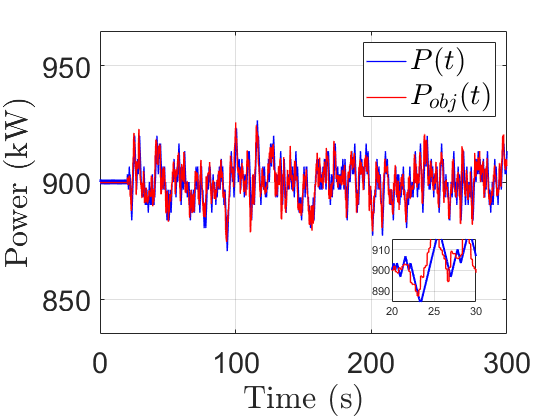

% Power curve 
figure(1)
clf
plot(t(200001:length(t))-200,P_t(200001:length(t)),"LineWidth",1,'Color','b')
hold on
plot(t(200001:length(t))-200,Pobj_t(200001:length(t)),"LineWidth",1,'Color','r')
grid on
% xlim([0.0 50.0])
ylim([835.0 965.0])
xlabel('Time (s)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
ylabel('Power (kW)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
legend({'$P(t)$','$P_{obj}(t)$'},"Interpreter","latex",'FontSize',22)
set(gca,'FontSize',22);
axes('Position',[0.7,0.28,0.15,0.15]); % Generating subgraphs if necessary
plot(t(20001:length(t))-200,P_t(20001:length(t)),"LineWidth",1.5,'Color','b')
hold on
plot(t(20001:length(t))-200,Pobj_t(20001:length(t)),"LineWidth",1,'Color','r')
grid on
set(gca,'FontSize',8);
xlim([20,30]); 
ylim([885,915]);

% Comfort state curve 
figure(2)
clf
for i=1:N
plot(t(200001:length(t))-200,x_t(i,200001:length(t)),"LineWidth",1)
hold on
grid on
end
ylim([0.4 0.6])
xlabel('Time (s)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
ylabel('$x(t)$',"Interpreter","latex",'FontSize',25,"LineWidth",2)
set(gca,'FontSize',22);

% v curve 
figure(3)

clf
for i=1:N
plot(t(200001:length(t))-200,v_t(i,200001:length(t)),"LineWidth",1)
hold on
grid on
end
ylim([-0.05 0.05])
xlabel('Time (s)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
ylabel('$v(t)$',"Interpreter","latex",'FontSize',25,"LineWidth",2)
set(gca,'FontSize',22);

% frequency deviation curve 
figure(4)

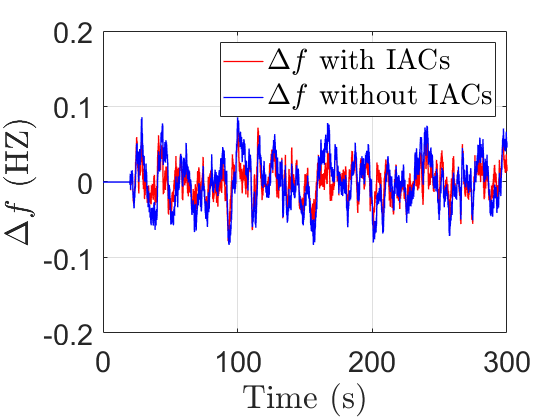

clf
plot(t(200001:length(t))-200,df_t(200001:length(t)),"LineWidth",1,'Color','r')
hold on
plot(t(200001:length(t))-200,df_t1(200001:length(t)),"LineWidth",1,'Color','b')
grid on
ylim([-0.2 0.2])
set(gca,'FontSize',22);
xlabel('Time (s)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
ylabel('$\Delta f$ (HZ)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
legend({['$\Delta f$ with IACs'],['$\Delta f$ without IACs']},"Interpreter","latex",'FontSize',22)

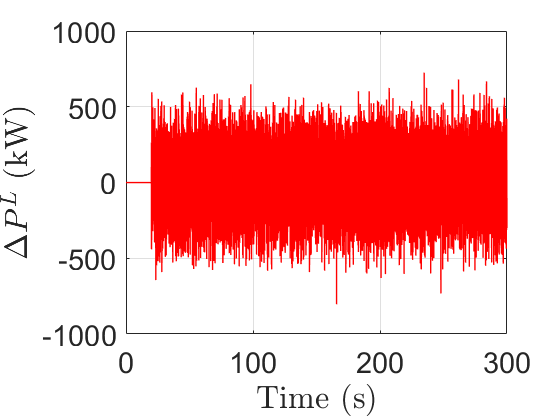

figure(5)
clf
plot(t(200001:length(t))-200,3600*dPL(200001:length(t)),"LineWidth",1,'Color','r')
grid on
xlabel('Time (s)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
ylabel('$\Delta P^{L}$ (kW)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
set(gca,'FontSize',22);

T = clock; 
time=[num2str(T(1)),num2str(T(2)),num2str(T(3)),'_',num2str(T(4)),num2str(T(5)),'_comprehensive','.mat'];
% save(time,'-v7.3')    